# Cardiac spot finding test

input_path = fullfile("../../Cardiac_201/test/cardiac_test.tif")
test_img = new_LoadMultipageTiff(input_path, 'uint8', false);

af_mr = new_MorphologicalReconstruction(test_img, "2d");
figure
imshowpair(test_img(:,:,1), af_mr(:,:,1))

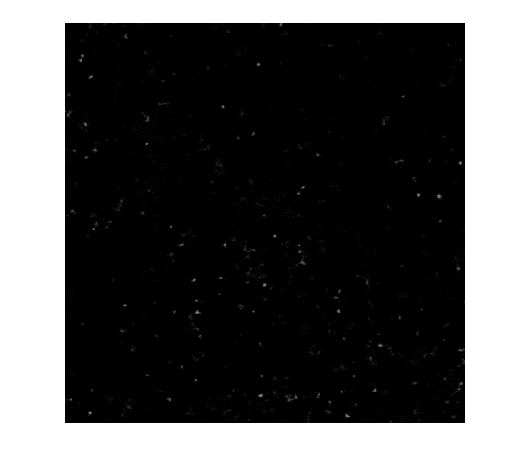

se = strel('disk', 2);

curr_slice = test_img(:,:,1);
marker = imerode(curr_slice, se); % Morphological opening is useful for removing small objects from an image while preserving the shape and size of larger objects in the image
figure
imshow(curr_slice)

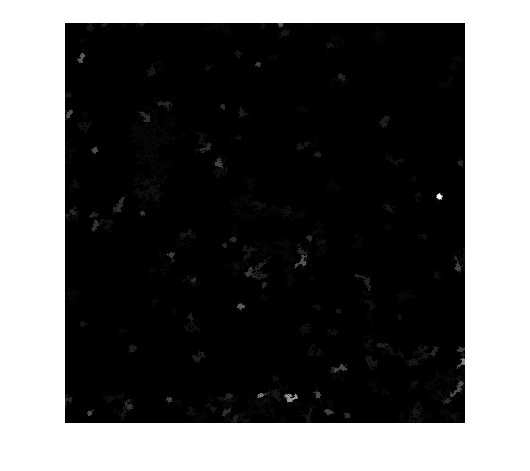

obr = imreconstruct(marker, curr_slice);
figure
imshow(obr, [])

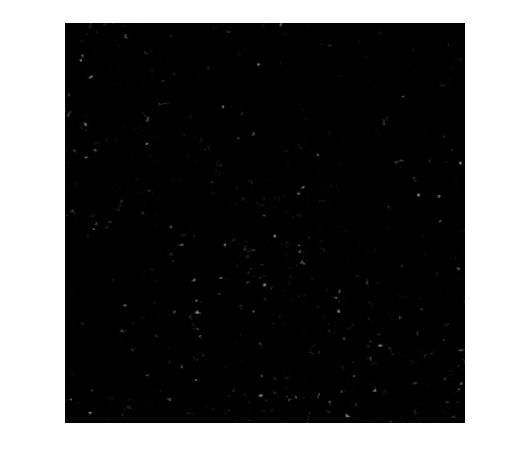

curr_out = curr_slice - obr;
figure
imshow(curr_out)

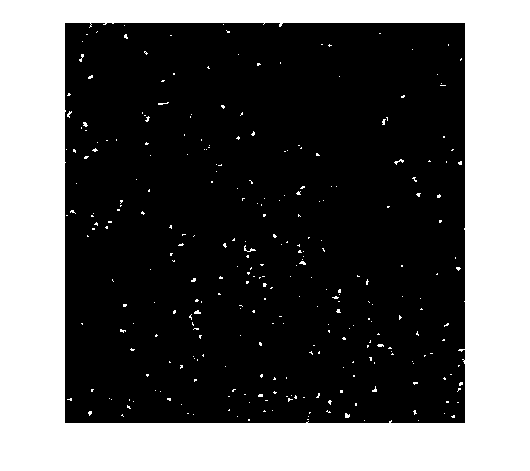

mask = imbinarize(curr_out,0.06);
figure
imshow(mask)

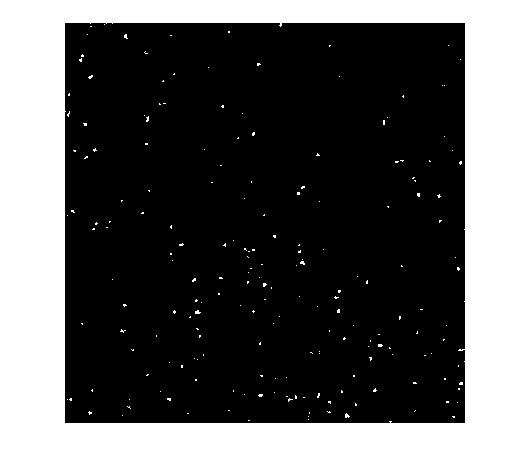


curr_out(~mask) = 0;
bw = imbinarize(curr_out);
bw = bwareaopen(bw, 1);
figure 
imshow(bw)

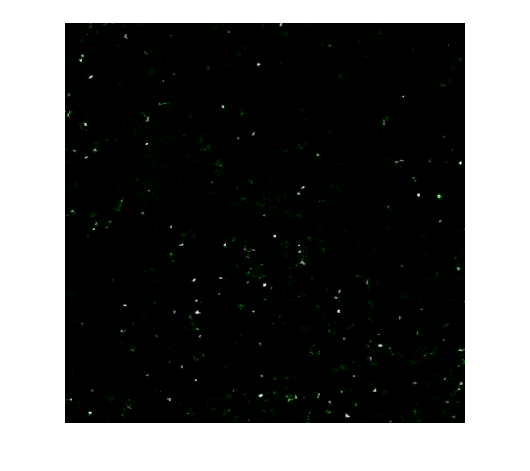


curr_out(~bw) = 0;
curr_out = imsubtract(imadd(curr_out, imtophat(curr_out, se)), imbothat(curr_out, se));
figure
imshowpair(curr_slice, curr_out)

input_img = af_mr;
quality_factor = 0.01;
volume_threshold = 1;
showPlots = true;
useGPU = false;


locations = [];

local_threshold = quality_factor;
% get barcode for each pixel
[base_call_stack, quality_matrix, barcodes] = GetBarcodes(input_img, local_threshold, useGPU);

Get barcodes for Round 1....Q: 1.00, C: 1814574[time = 0.92 s]



% get global quailty
base_call_qual = quality_matrix(quality_matrix ~= 0);
base_call_qual = reshape(base_call_qual, 1, numel(base_call_qual));

% get global quailty threshold
quality_threshold = quality_factor * max(quality_matrix, [], 'all');
fprintf('The global quality score threshold for barcode calling is: %4.2f \n', quality_threshold)

The global quality score threshold for barcode calling is: 0.01 


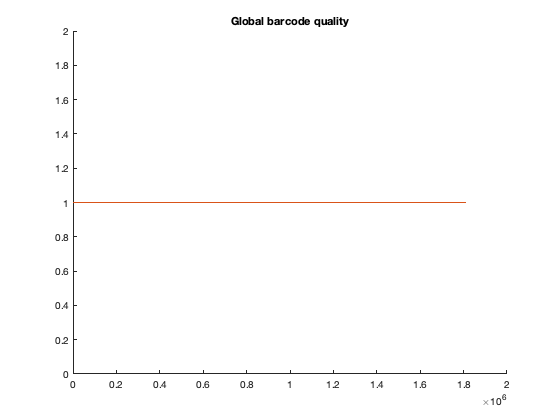


if showPlots
    figure
    hold on
    plot(sort(base_call_qual, 'descend'))
    plot(1:numel(base_call_qual), ones(numel(base_call_qual),1) * mean(base_call_qual))
    title('Global barcode quality')
    hold off
end

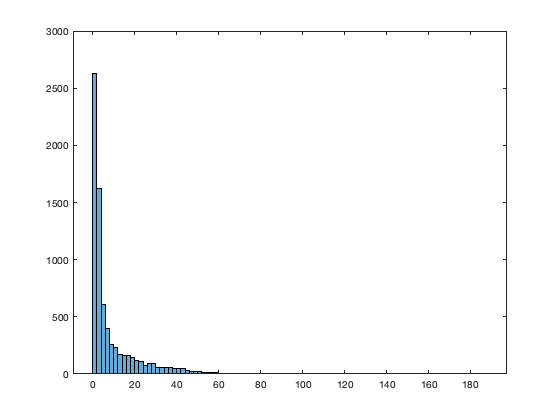


%     % fill missing value
%     for i =1:1
%     base_call_stack(base_call_stack == 0) = NaN;
%     base_call_stack = fillmissing(base_call_stack, 'movmedian', [1 1]);
%     base_call_stack = fillmissing(base_call_stack, 'movmedian', [1 1], 2);
%     base_call_stack = fillmissing(base_call_stack, 'constant', 0);
%     
%     quality_matrix(quality_matrix == 0) = NaN;
%     quality_matrix = fillmissing(quality_matrix, 'movmedian', [1 1]);
%     quality_matrix = fillmissing(quality_matrix, 'movmedian', [1 1], 2);
%     quality_matrix = fillmissing(quality_matrix, 'constant', 0);
%     end

%     % iterate through all barcode clusters
%     Ncluster = numel(barcodes);
%     props = {'Volume'; 'Centroid'};
%     % props = {'Volume'; 'Centroid'; 'EquivDiameter'; 'VoxelIdxList'};
% 
%     all_volume = []; 
%     fprintf('Iterate through clusters...')
%     tic;
%     parfor c = 1:Ncluster
% 
%         curr_barcode = barcodes(c); 
%         curr_img = zeros(size(base_call_stack)); 
%         curr_img(base_call_stack == curr_barcode & quality_matrix > quality_threshold) = 1; % global quality filtration 
%         curr_img = logical(curr_img);
% 
% 
%         curr_stats = regionprops3(curr_img, props);
%         all_volume = [all_volume; curr_stats.Volume]; %% WARNING
%         curr_valid_cc = curr_stats(curr_stats.Volume > volume_threshold, "Centroid"); % volume filtration
%         curr_valid_cc = int16(table2array(curr_valid_cc));
%         if ~isempty(curr_valid_cc)       
%             locations = [locations; curr_valid_cc]; %% WARNING
%         end
%         
%     end
%     
%     fprintf(sprintf('[time = %.2f s]\n', toc));
% 
%     
%     if showPlots
%         figure
%         histogram(all_volume)
%     end


% NEW
if useGPU
    base_call_stack = gather(base_call_stack);
end

out_stack = zeros(size(base_call_stack));

for z=1:size(base_call_stack,3)
    bmask = boundarymask(base_call_stack(:,:,z));
    base_bw = imbinarize(base_call_stack(:,:,z));
    base_bw = imfill(base_bw, 'holes');
    bmask = imcomplement(bmask);
    out_bw = base_bw .* bmask;
    out_stack(:,:,z) = out_bw;
end

props = {'Volume'; 'Centroid'};
out_stack(quality_matrix <= quality_threshold) = 0; % global quality filtration 
curr_stats = regionprops3(logical(out_stack), props);
curr_valid_cc = curr_stats(curr_stats.Volume > volume_threshold, "Centroid"); % volume filtration
curr_valid_cc = int16(table2array(curr_valid_cc));
if ~isempty(curr_valid_cc)       
    locations = [locations; curr_valid_cc]; %% WARNING
end

if showPlots
    figure
    histogram(curr_stats.Volume)
end

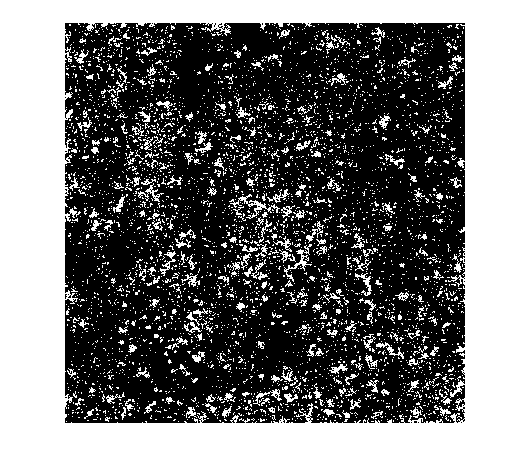

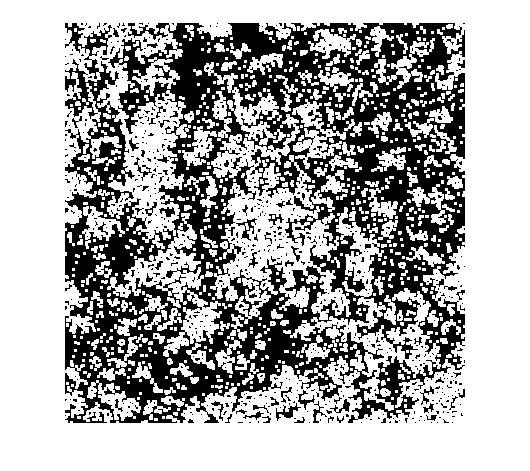

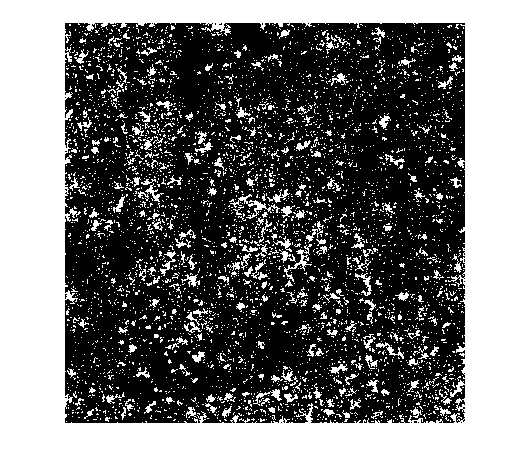

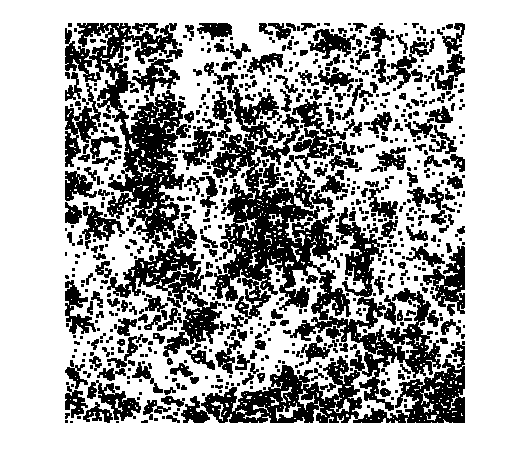

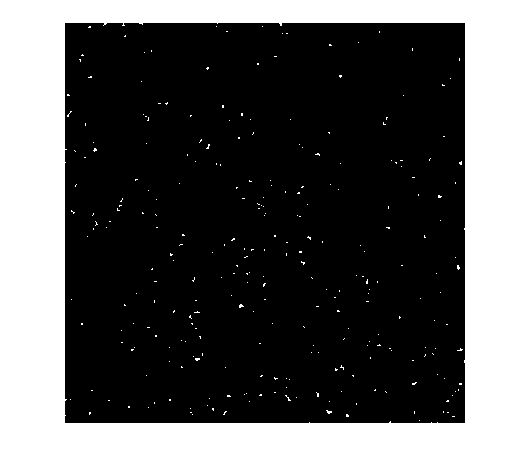

for z=1:1
    figure
    imshow(base_call_stack(:,:,z))
    bmask = boundarymask(base_call_stack(:,:,z));
    figure
    imshow(bmask)
    base_bw = imbinarize(base_call_stack(:,:,z));
    base_bw = imfill(base_bw, 'holes');
    figure
    imshow(base_bw)
    bmask = imcomplement(bmask);
    figure
    imshow(bmask)
    out_bw = base_bw .* bmask;
    figure
    imshow(out_bw)
    out_stack(:,:,z) = out_bw;
end

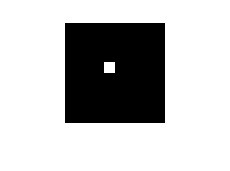

bw_test = zeros(100,100);
bw_test(40:50, 40:50) = 1;
bw_test = logical(bw_test);
figure
imshow(bw_test)

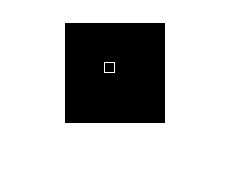


[B, L] = bwboundaries(bw_test);
bw_bd = zeros(size(bw_test));
boundary = B{1};
for i=1:size(boundary,1)
    bw_bd(boundary(i,1), boundary(i,2)) = 1;
end

% for k = 1:length(B)
%    boundary = B{k};
%    bw_bd(boundary(:,1), boundary(:,2)) = 1;
% end

figure
imshow(bw_bd)

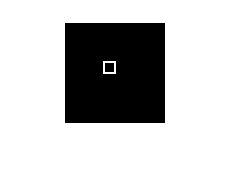


bw_bd2 = boundarymask(bw_test);
figure
imshow(bw_bd2)

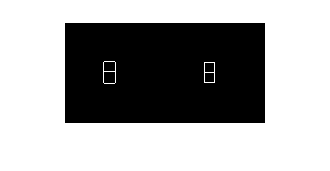


bw_test = zeros(100,100);
bw_test(40:50, 40:50) = 1;
bw_test(50:60, 40:50) = 2;

%se = ones(3);
se = [ ...
    0,1,0; ...
    1,1,1; ...
    0,1,0; ...
    ];
    
bw_bd3 = (imdilate(bw_test,se) > bw_test) | (imerode(bw_test,se) < bw_test);
figure
imshowpair(imdilate(bw_test,se) > bw_test, imerode(bw_test,se) < bw_test, 'montage')

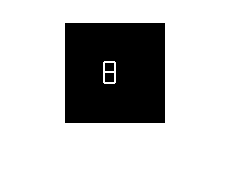

figure
imshow(bw_bd3)